Promentilla, Jose Mikhael Uriel

## Zero Crossings

Zero crossings are points on the signal when the signal crosses the x-axis baseline of zero. It is when the signal changes from a

positive signal to a negative signal or vice versa. It is not considered a zero crossing if the signal does not cross from a positive value

to the negative value, even if the value reaches zero on certain points.

How does zero crossing relate to vowels and consonants?

Hypothesis: since vowels has a tone or pitch and can vary in speech, in areas where there are vowels, there would be a significantly

higher count of zero crossings.

## Speech Signal

Using the PRAAT software, the speech signal was able to be decoded.

The speech signal includes a female saying the filipino phrase: "Pang lima siya sa sampung magkakapatid".

% Read the file
filename = 'speech_MP1.wav';
[signal,Fs] = audioread(filename);
info = audioinfo(filename);
% plot(signal);

% Split/Segment into Frames with overlapping 
rate = 16000; %16000 per second
duration = 0.03; %30ms in seconds
overlap = 16000 * 0.015; %total samples in 15ms
framelen = rate * duration; %=480 of length by 155 frames
N = length(signal);
num_frames = floor(N/framelen);
allframes = buffer(signal,framelen,overlap);
% plot(allframes);

% Count zero crossings per frame
zcd = dsp.ZeroCrossingDetector;
numZeroCross = zcd(allframes);
% plot(numZeroCross);

% Plot graphs
f1 = figure

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [427 306 512 384]
       Units: 'pixels'

  Show all properties


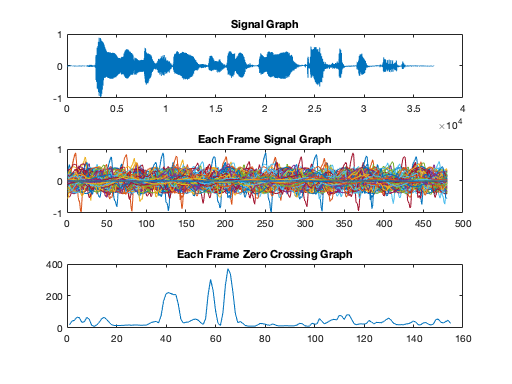

subplot(3,1,1);
plot(signal);
title('Signal Graph');
subplot(3,1,2);
plot(allframes);
title('Each Frame Signal Graph');
subplot(3,1,3);
plot(numZeroCross);
title('Each Frame Zero Crossing Graph');


% Adjust zero crossings to superimpose zero crossing graph to signal graph 
[zcRow, zcCol] = size(numZeroCross);
numOfSpaces = floor(N / zcCol); %divide the entire audio into frames
imposedZC = NaN(N, 1);
ctr = 1;
for i = 1:numOfSpaces:N
    if i <= N && ctr <= zcCol 
        imposedZC(i) = numZeroCross(ctr);
    end
    ctr = ctr+1;
end
imposedZC = fillmissing(imposedZC,'nearest');
% stairs(imposedZC);

% Plot superimpose of zero crossing to signal
f2 = figure

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [427 306 512 384]
       Units: 'pixels'

  Show all properties


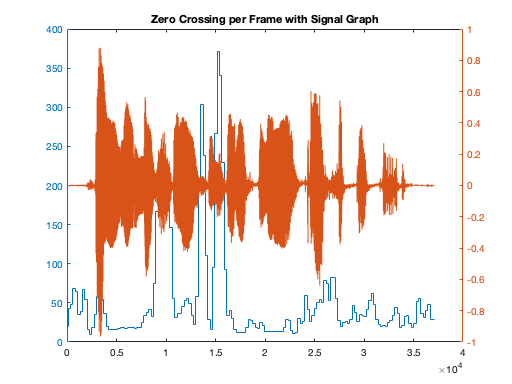

yyaxis left;
stairs(imposedZC);
yyaxis right;
plot(signal);
title('Zero Crossing per Frame with Signal Graph');

### Zero Crossings Observations

Using the PRAAT software the top two areas of zero crossings were listened to.

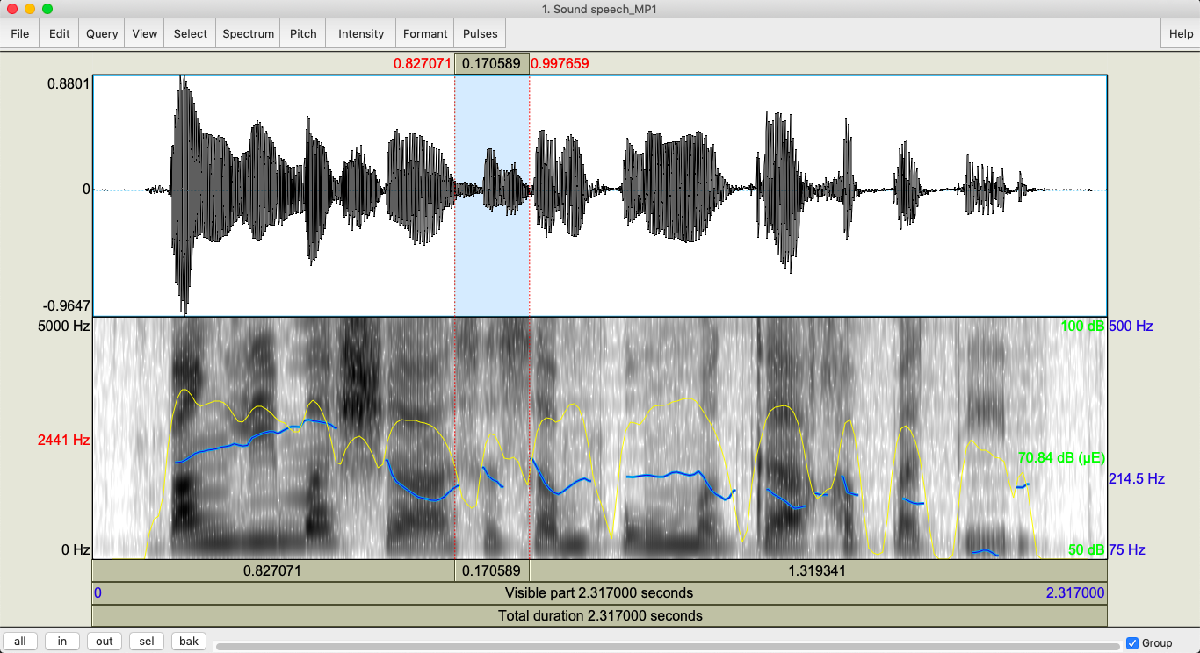

That area of the speech includes the "sa sa(mpung)" phrase. It can be observed that the in both cases, the vowels follow the consonant. The initial hypothesis of the vowel being a factor in a higher count of zero crossings is still plausible. From this, it can also be hypothesized that a consonant following a vowel would result into a higher count of zero crossings if one considers consonants to be negative signal values and and vowels to be positive signal values. But this could also be contradicted as one might wonder why there was such a big difference in the zero crossings of "sa sa(mpuing)" and "(mag)kaka(patid)" when both parts of the phrases sound the same.

Another hypothesis might be that although the vowels matter less, what matters more is the speed of the change in sounds. The "sa sa(mpung)" phrase is relatively fast when compared to the other parts of the speech. The third highest zero crossing of "siya" also supports this claim as it also has a faster tempo. This might also explain why "(mag)kaka(patid)" has far less zero crossings in that frame because the "kaka" part is elongated when spoken. 

## Maximum Magnitude

The maximum magnitude of a frequecny is considered as the dominant frequecny. The dominant frequency is when a frequency analysis is done, such as a Fast Fourier Transform (FFT), would have the greatest amplitude in that spectrum.

Hypothesis: As measured in the signal graph, the maximum magnitude would align with the signal.

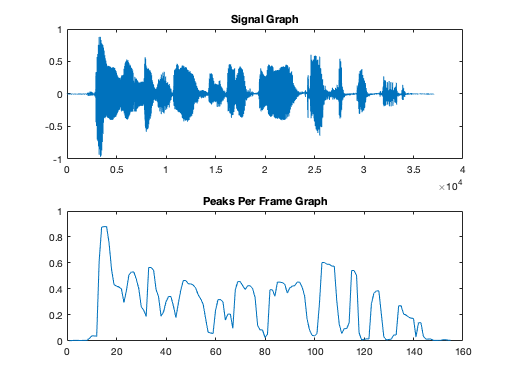

% Read the file
filename = 'speech_MP1.wav';
[signal,Fs] = audioread(filename);
info = audioinfo(filename);
% plot(signal);

% Split/Segment into Frames with overlapping 
rate = 16000; %16000 per second
duration = 0.03; %30ms in seconds
overlap = 16000 * 0.015; %total samples in 15ms
framelen = rate * duration; %=480 of length by 155 frames
N = length(signal);
num_frames = floor(N/framelen);
allframes = buffer(signal,framelen,overlap);
% plot(allframes);

% Get peaks of each frame
[row, col] = size(allframes);
peaksperframe = zeros(1, col);
for i=1:col
    peaksperframe(i) = max(findpeaks(allframes(:,i)));
end
% plot(peaksperframe)

% Get peaks per FFT Frame
% 1. FFT each frame
% 2. Get peak of each FFT
[row, col] = size(allframes);
fftperframe = zeros(1, col);
for i=1:col
    fftperframe(i) = max(findpeaks( abs(fft(allframes(:,i) - mean(allframes(:,i)))/length(allframes(:,i))) ) );
end
% plot(fftperframe)

% Plot graphs
f1 = figure;
subplot(2,1,1);
plot(signal);
title('Signal Graph');
subplot(2,1,2);
plot(peaksperframe);
title('Peaks Per Frame Graph');

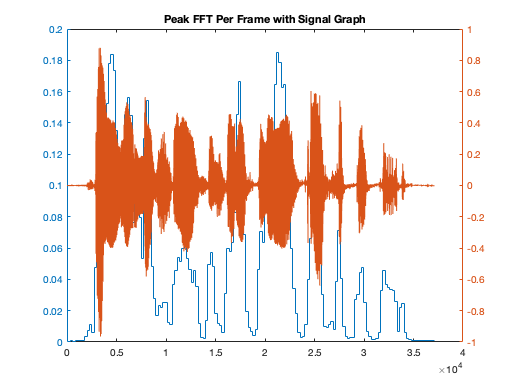


% Adjust FFT per frame to superimpose on the signal graph
[fftRow, fftCol] = size(fftperframe);
numOfSpaces = floor(N / fftCol);
imposedFT = NaN(N, 1);
ctr = 1;
for i = 1:numOfSpaces:N
    if i <= N & ctr <= fftCol 
        imposedFT(i) = fftperframe(ctr);
    end
    ctr = ctr+1;
end
imposedFT = fillmissing(imposedFT,'nearest');
% stairs(imposedFT);

% Plot superimpose of FFT to signal graph
f2 = figure;
yyaxis left;
stairs(imposedFT);
yyaxis right;
plot(signal);
title('Peak FFT Per Frame with Signal Graph');

### Maximum Magnitude Observations:

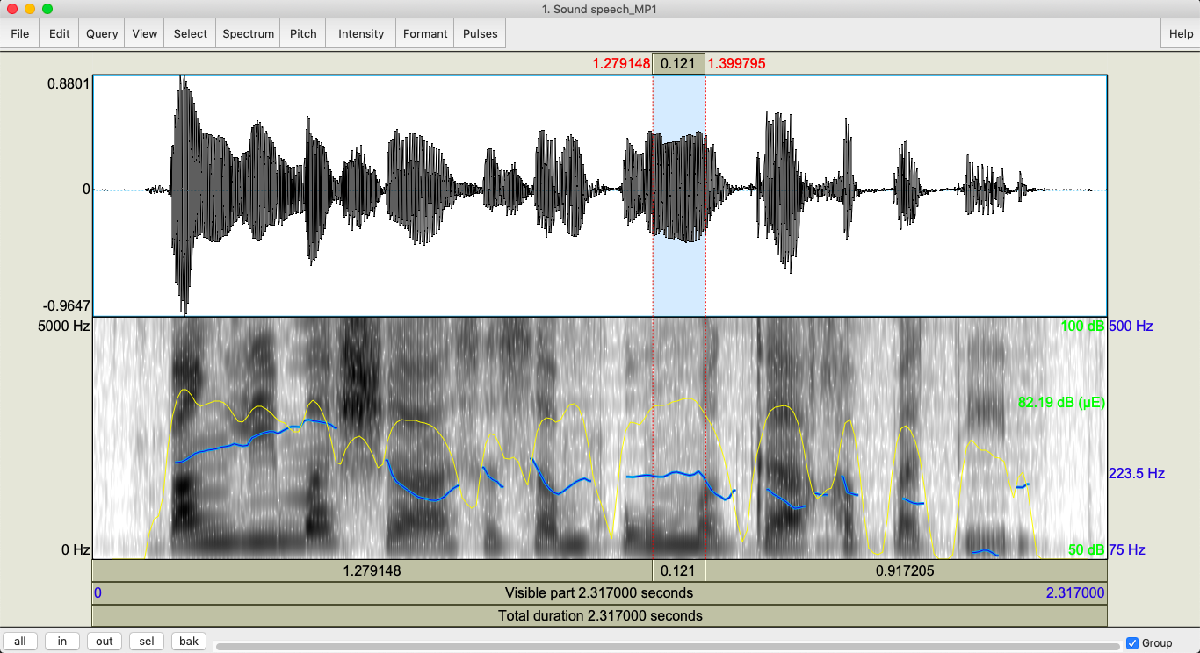

The maximum magnitudes of the FFT aligned with the measured high magnitudes of the signal graph although a bit delayed. The highest magnitudes in the speech includes the phrase "(samp)ung mag". Based from this observation, it can be hypothesized that the higher magnitudes are dependend from the transitions of the mouth. When the phrase "ung" is spoken, it seems that the mouth or tongue's position to say the phrase "mag" is positioned in opposite. The "ung" sound positions the mouth openly and upwardly while the "mag" sound positions the mouth flatly and downwardly. Though vowels are still a major factor in determining magnitude because of its capablity to have varying tones, it could be further hypothesized such that the combinations of vowels and consonants and their transition is what determines the magnitude.

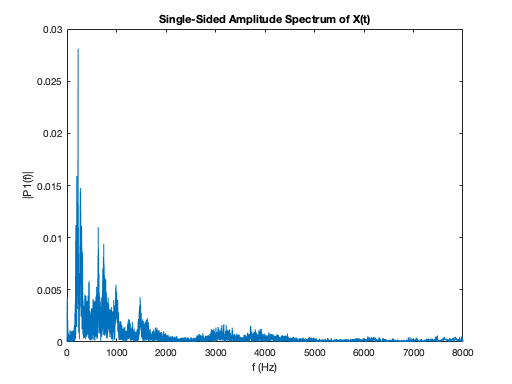



% Get entire signal FFT and adjust to single-sided amplitude
f3 = figure;
Fs = rate;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = N;             % Length of signal
t = (0:L-1)*T;        % Time vector
Y = fft(signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


% entire signal FFT 2
% entirefft = abs(fft(signal - mean(signal))/length(signal));
% plot(entirefft);
